# KRISS_Planar_NF2FF Live Script

## Matlab Initialization

clear; clc; close all
addpath './lib'

## Select Input Data (Change Here!!)

Select input data, including NF measurement results, probe gain, and calibration data, to be loaded

### *Description*

#### Port

- 1: Port 1

- 2: Port 2

#### Frequency

- Measured frequency in GHz 

- 4, 5, 6 available

data_id = [1 5]; % [Port Frequency]

## Load User Variables

uservar_name = sprintf("./rawdata/UserVar_BFT_QRH_P%d_%dGHz_241106.m", ...
  data_id(1), ...
  data_id(2) ...
);

user_var = load_uservar(uservar_name);
probe = Probe(user_var);
reflectometer = Reflectometer(user_var);

Here, we are loading variables below related to measurements and NFFF transformation.

To modify the variables, please edit UserVar.m

- target_path_Hpol: path for Hpol NF measurement dataset (.pnf)

- target_path_Vpol: path for Vpol NF measurement dataset (.pnf)

- probe_Ax: width of OEWG aperture in meters

- probe_Ay: height of OEWG aperture in meters

- probe_gain: boresight gain of OEWG

- probe_gamma: reflection coefficient of OEWG port

- reflectometer_gamma_load: reflection coefficient of AUT side VNA reference plane (P1)

- reflectometer_gamma_source: reflection coefficient of OEWG side VNA reference plane (P2)

- reflectometer_thru: P1 to P2 thru transmission coefficient

- aut_gamma: reflection coefficient of AUT port

- aut_coor: 3-D coordinates of AUT w.r.t. OEWG initial location (Not used currently)

- dth: theta resolution for spherical transformation

- dph: phi resolution for spherical transformation

- num_fft: number of fft for wave spectrum calculation

## Planar Near Field

Class with PNF measurement data

- x: x-coordinates of measurement data

- dx: x step of measurement data

- nf: Number of measurement points in x-axis

- y: y--coordinates of measurement data

- dy: y step of measurement data

- ny: Number of measurement points in y-axis

- coor: Array of [x, y] coordinates at each measurement point

- f: List of frequencies measured

- fi: Target frequency

- E_H: Horizontal E-field data

- E_V: Vertical E-field data

### *Initialization*

Initialize PlanarNearField class and load pnf file

PlanarNearField class contains PNF measurement information

planar_NF = PlanarNearField();
planar_NF = planar_NF.load_pnf(user_var);

x =    -0.5250   -0.4965   -0.4680   -0.4395   -0.4110   -0.3825   -0.3540   -0.3255   -0.2970   -0.2685   -0.2400   -0.2115   -0.1830   -0.1545   -0.1260   -0.0975   -0.0690   -0.0405   -0.0120    0.0165    0.0450    0.0735    0.1020    0.1305    0.1590    0.1875    0.2160    0.2445    0.2730    0.3015    0.3300    0.3585    0.3870    0.4155    0.4440    0.4725    0.5010


### *Plot loaded PNF E-field data *

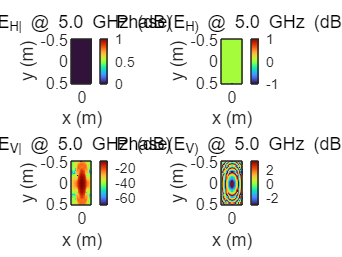

figure(101); planar_NF.plot_E();

## Planar Wave Spectrum

- f: Target frequency

- lambda: wavelength

- k: wave number

- coor: Array of [x, y] coordinates at each measurement point and zero padding location

- kx_grid: x-coordinates of propagation vector for each data

- ky_grid: y-coordinates of propagation vector for each data

- kz_grid: z-coordinates of propagation vector for each data

- kx: x-axis of propagation vector

- ky: y-axis of propagation vector

- nkx: number of points @ x-axis

- nky: number of points @ y-axis

- dkx: point step @ x-axis

- dky: point step @ y-axis

- f_x: Plane wave spectrum function @ x direction 

- f_y: Plane wave spectrum function @ y direction 

- gain_constant: Coefficient for gain calculation

### *Transform PNF data to planar wave spectrum*

- $f_x(k_x, k_y)=\int_{-b/2}^{+b/2} \int_{-a/2}^{+a/2}  
                     { 
                            E_{xa} ({x^{'},  y^{'}, z^{'}=0)
                            e^{+j (k_x x^{'} + k_y y^{'}) }
                     }
                  }       dx^{'} dy^{'}$                (17-7a)  in Balanis [3]

- $f_y(k_x, k_y)=\int_{-b/2}^{+b/2} \int_{-a/2}^{+a/2}  
                     { 
                            E_{ya} ({x^{'},  y^{'}, z^{'}=0)
                            e^{+j (k_x x^{'} + k_y y^{'}) }
                     }
                  }       dx^{'} dy^{'}$                (17-7b) in Balanis [3]

which corresponds to:

- 
$$f_x (k_x, k_y) = F_k(E_H) e^{jk_z \lambda}$$


- 
$$f_y (k_x, k_y) = F_k(E_V) e^{jk_z \lambda}$$


where $F_k$ indicates Fourier transform according to k-space and

- $k_z = \sqrt{k^2 - k_x ^ 2 - k_y ^2}$ .

Here, $k_x$ and $k_y$ are k-space axes of which value is from $\frac {- \pi} {\Delta k_x}$ to $\frac {\pi} {\Delta k_x}$ with $\frac{2 \pi} {\#FFT \cdot \Delta k_x}$ step and vice versa.

planar_wave_spectrum = planar_NF.calculate_planar_wave_spectrum(user_var);

### *Plot planar wave spectrum*

% figure(201); planar_wave_spectrum.plot();

## Spherical Wave Spectrum

- theta: theta axis

- phi: phi axis

- dth: theta step

- dph: phi step

- f_x: Plane wave spectrum function @ x direction for polar coordinates

- f_y: Plane wave spectrum function @ y direction  for polar coordinates

### *Transform planar wave spectrum to spherical wave spectrum*

Polar coordinates $\left( \theta , \phi , k \right)$ corresponds to cartesian coordinares $\left( k \sin(\theta) \cos(\phi) , k \sin(\theta) \sin(\phi), - \right)$.

We convert defined polar coordinates to cartesian coordinates, then perform interpolation to find wave spectrum function values at corresponding cartesian coordinates.

spherical_wave_spectrum = planar_wave_spectrum.convert_to_spherical(user_var);

## Spherical Far-Field

- E_theta: Electric field @ theta direction

- E_phi: Electric field @ phi direction

- W: Radiated power

- U: Radiated intensity

### *Transform spherical wave spectrum to spherical far-field*

- 
$$E_{\theta, FF} (\theta , \phi ) = {f_x} (\theta , \phi ) \cos(\phi) + {f_y} (\theta , \phi ) * \sin(\phi)$$


- 
$$E_{\phi , FF} (\theta , \phi ) = \cos (\theta ) \left\{ -f_x (\theta , \phi ) * \sin ( \phi ) + f_y (\theta , \phi ) * \cos ( \phi ) \right\}$$


spherical_FF = spherical_wave_spectrum.calculate_farfield();

### *Plot spherical E-field*

% figure(501); spherical_FF.plot_E();

### *Calculate radiation intensity (U)*

- 
$$U (\theta , \phi ) =  \left|E_\theta  (\theta , \phi ) \right | ^2 + \left|E_\phi (\theta , \phi ) \right| ^2$$


spherical_FF = spherical_FF.calculate_U();

### *Plot radiation intensity (U)*

% figure(502); spherical_FF.plot_U();

### *Calculate radiated power before probe correction (W)*

- 
$$W (\theta , \phi ) = E_\theta (\theta , \phi ) * conj( E_\theta (\theta , \phi ) ) + E_\phi (\theta , \phi )* conj( E_\phi (\theta , \phi ))$$


spherical_FF = spherical_FF.calculate_W();

### *Plot radiated power before probe correction (W)*

% figure(503); spherical_FF.plot_W();
% title('Before probe correction')

## Probe Correction

### *Calculate probe pattern*

probe = probe.calculate_pattern(spherical_FF);

### *Plot probe pattern*

% figure(401); probe.plot_pattern()

### *Do probe correction*

spherical_FF_corrected = spherical_FF.probe_correction(probe);

## Calculate and Plot Final Results

### *Plot radiated power after probe correction (W)*

% figure(504); spherical_FF_corrected.plot_W();
% title('After probe correction')

### *Calculate E- and H-plane directivity before and after probe correction*

spherical_FF = spherical_FF.calculate_EH();
spherical_FF_corrected = spherical_FF_corrected.calculate_EH();

### *Plot E- and H-plane directivity before and after probe correction*

% figure(505)
% spherical_FF.plot_EH();
% spherical_FF_corrected.plot_EH();
% legend('Before', 'after') 

### *Calculate gain*

spherical_FF_corrected = spherical_FF_corrected.calculate_gain(planar_wave_spectrum, reflectometer, probe);

### *Plot gain*

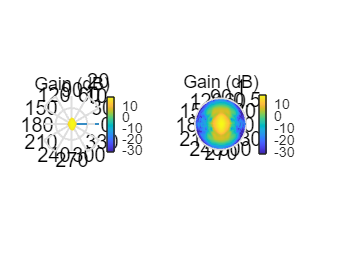

figure(506)
spherical_FF_corrected.plot_gain();

### *Report gain*

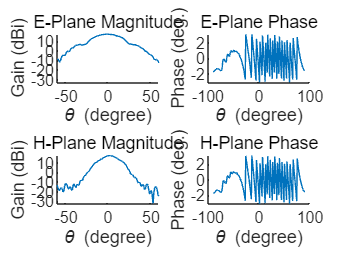

Peak gain @ 5.00 GHz = 17.4044 dB @ phi = 62.0 deg / theta = 88.0 deg
Peak E-plane gain @ 5.00 GHz = 17.1952 dB
Peak H-plane gain @ 5.00 GHz = 17.3622 dB


figure(507)
spherical_FF_corrected = spherical_FF_corrected.report_gain();

## References

[1] A.C. Newell, "Near Field Antenna Measurement Theory, Planar, Cylindrical and Spherical", unpublished powerpoint, NSI, 2009.

[2] A.C. Newell, R.D. Ward, and E.J. McFarlane, "Gain and power parameter measurements using planar near-field techniques," Antennas and Propagation, IEEE Transactions on,  vol. 36, 1988, pp. 792-803.

[3] C. A. Balanis, Antenna theory: analysis and design. 3rd edition, Hoboken, NJ: Wiley Interscience, 2005.